# DISEÑO FRECUENCIAL

CONTROLADOR EN ADELANTO

%Hallar el valor de K
s=tf('s');
G=1/(s*(s+2))%se evalua el limite de FT


G =
 
      1
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



dcgain(s*G)

ans = 0.5000

kv=10;
k=kv/dcgain(G*s)

k = 20

G1=k*G


G1 =
 
     20
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



dcgain(G1*s)

ans = 10

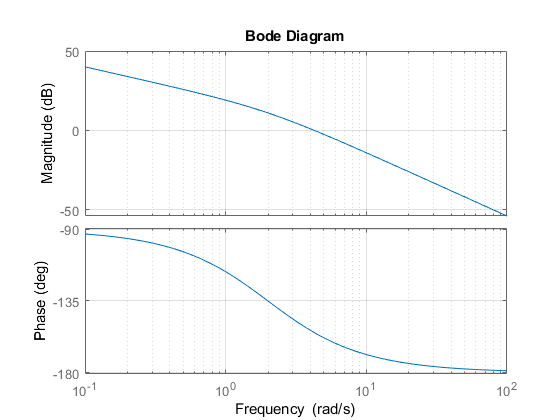

bode(G1),grid

[MGc,MFc]=margin(G1) 

MGc = Inf

MFc = 25.1801


%Hallar MF


MF=70-25.1801+5

MF = 49.8199


%calcular alfa (atenuación)

a=(1-sin(deg2rad(MF)))/(1+sin(deg2rad(MF)))

a = 0.1338


Gm=-20*log10(1/sqrt(a))

Gm = -8.7363

Hallar wm

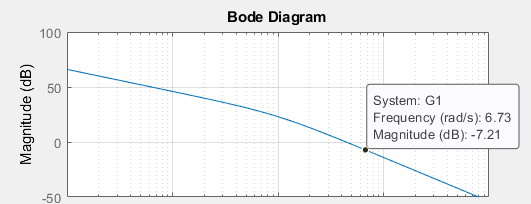

wm=7.3

wm = 7.3000


%Hallar valor de T

T=1/(wm*sqrt(a))

T = 0.3745

z=1/T

z = 2.6700

p=1/(a*T)

p = 19.9589

Kc=k/a

Kc = 149.5060

C=zpk(-z,-p,Kc)


C =
 
  149.51 (s+2.67)
  ---------------
     (s+19.96)
 
Continuous-time zero/pole/gain model.




%Probar controlador, si cumple con especificaciones

L=C*G


L =
 
   149.51 (s+2.67)
  -----------------
  s (s+19.96) (s+2)
 
Continuous-time zero/pole/gain model.



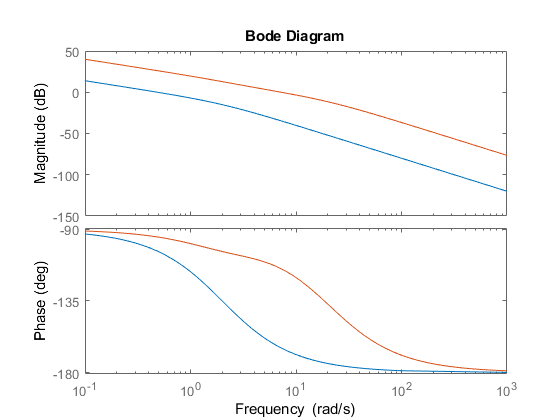

bode(G,L);

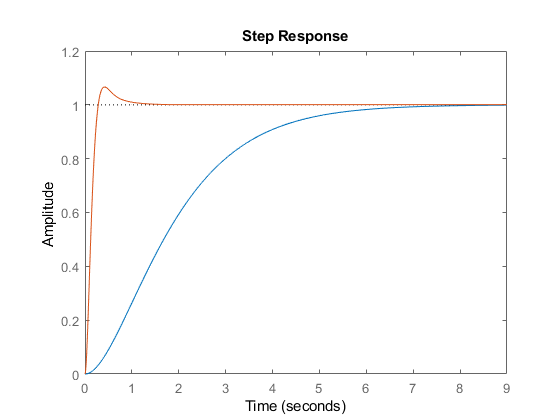

T=feedback(G,1);
Tc=feedback(G*C,1);
step(T,Tc)

[MGc,MFc,Wcg,Wcf]=margin(L) 

MGc = Inf

MFc = 65.2713

Wcg = Inf

Wcf = 7.2350